# PIPPET simulations for manuscript

## © Jonathan Cannon, MIT, 2020

make_sounds = false; % Set this to create sound examples to go with experiments
sp = sound_params();

components_path = 'stimulus_components/'

stretch = 1.35; % for easier listening
if make_sounds
    metronome = 0:.5:6;
    identities = sp.beep_index*ones(size(metronome));
    snd = stim_maker_etime(stretch*metronome, identities, sp);
    audiowrite('sounds/metonome.wav', snd, 44100);
end

## Phase response for fixed V

Expecting four evenly spaced events, equally. Plots are based on the assumption that each event is reached with identical phase uncertainty.

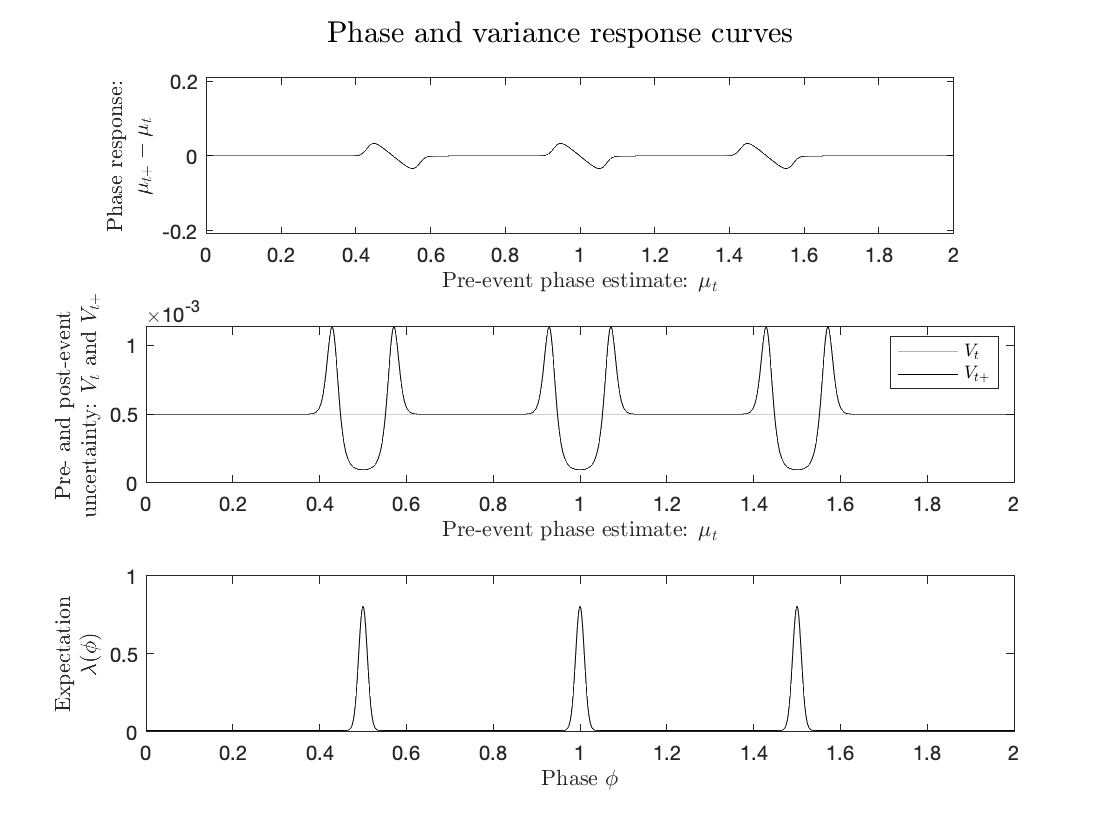

params = PIPPET_params(...
    'means_unit', [.5],...
    'expected_period', .5,...
    'expected_cycles', 3,...
    'event_times', []);

% lambda_0 = .00000001;
phi_list = 0:.002:2;

V = .0005;

phibar_list = zeros(size(phi_list));
V_list = zeros(size(phi_list));
for i = 1:length(phi_list)
    phibar_list(i) = params.streams{1}.phi_hat(phi_list(i), V);
    V_list(i) = params.streams{1}.V_hat(phibar_list(i), phi_list(i), V);
end

PRC = phibar_list - phi_list;

figure()
subplot(3,1,1)
plot(phi_list, PRC, 'k')
xlim([min(phi_list), max(phi_list)])
%axis equal
% ylabel({'Phase response:';'$\mu_{t+}- \mu_{t-}$'},'Interpreter','Latex')
% xlabel({'Pre-event phase estimate: $\mu_{t-}$'},'Interpreter','Latex')
ylabel({'Phase response:';'$\mu_{t+}- \mu_{t}$'},'Interpreter','Latex')
xlabel({'Pre-event phase estimate: $\mu_{t}$'},'Interpreter','Latex')
axis('equal')
%set(get(gca, "YLabel"), 'Rotation', 0)

subplot(3,1,2)
plot(phi_list, zeros(size(phi_list))+V, 'color', [.7,.7,.7])
hold on

plot(phi_list, V_list, 'k')
ylabel({'Pre- and post-event';'uncertainty: $V_{t}$ and $V_{t+}$'},'Interpreter','Latex')
%xlabel({'Pre-event phase estimate: $\mu_{t-}$'},'Interpreter','Latex')
xlabel({'Pre-event phase estimate: $\mu_{t}$'},'Interpreter','Latex')
legend('$V_{t}$','$V_{t+}$','Interpreter','Latex')
%set(get(gca, "YLabel"), 'Rotation', 0)

subplot(3,1,3)
plot(phi_list, params.streams{1}.expect_func(phi_list), 'k')
ylabel({'Expectation';'$\lambda(\phi)$'},'Interpreter','Latex')
xlabel('Phase $\phi$','Interpreter','Latex')
%ylim([min(log(params.streams{1}.expect_func(phi_list)))-.2, max(log(params.streams{1}.expect_func(phi_list)))+.2])
%set(get(gca, "YLabel"), 'Rotation', 0)

sgtitle('Phase and variance response curves','Interpreter','Latex')

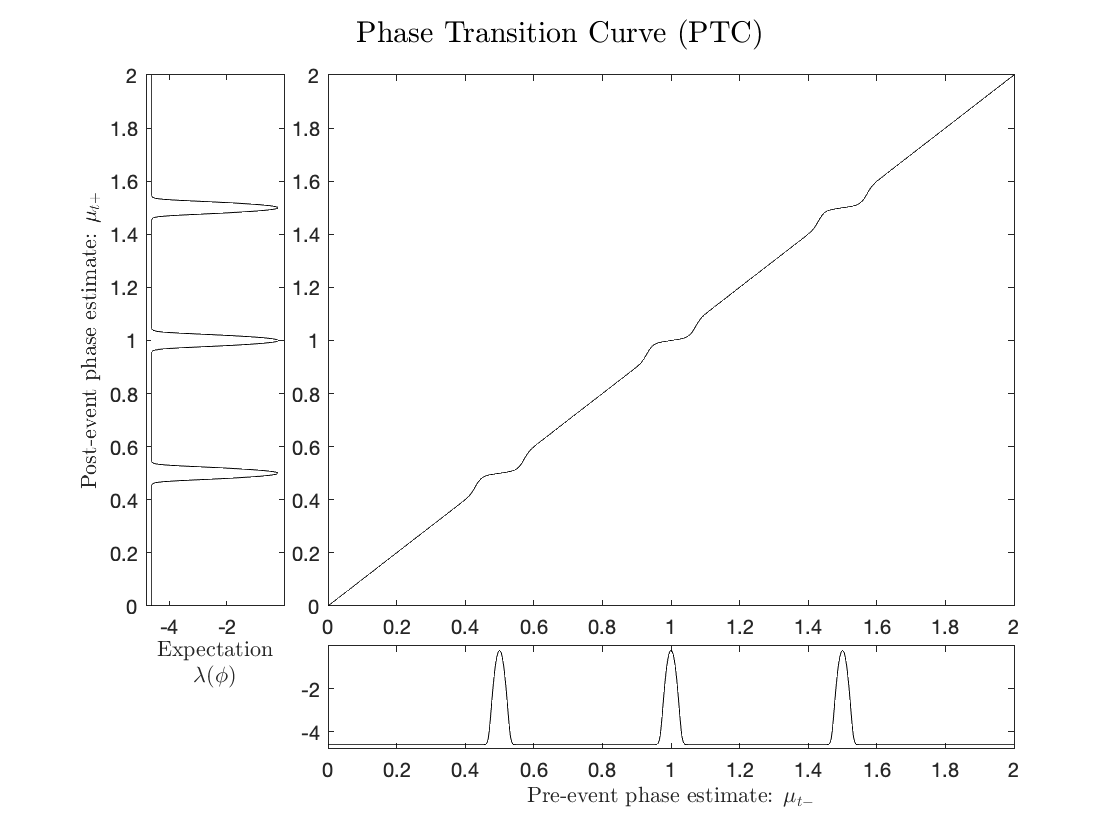


figure()

subplot(5,5, [2,3,4,5, 7,8,9,10, 12,13,14,15, 17,18,19,20])
plot(phi_list, phibar_list, 'k')
xlim([min(phi_list), max(phi_list)])
ylim([min(phi_list), max(phi_list)])

subplot(5,5, [1,6,11,16])
plot(log(params.streams{1}.expect_func(phi_list)), phi_list, 'k')
%ylabel('Post-event phase estimate: $\mu_{t+}$','Interpreter','Latex')
ylabel('Post-event phase estimate: $\mu_{t+}$','Interpreter','Latex')
xlim([min(log(params.streams{1}.expect_func(phi_list)))-.2, max(log(params.streams{1}.expect_func(phi_list)))+.2])
xlabel({'Expectation';'$\lambda(\phi)$'},'Interpreter','Latex')

subplot(5,5, [22,23,24,25])
plot(phi_list, log(params.streams{1}.expect_func(phi_list)), 'k')
%xlabel('Pre-event phase estimate: $\mu_{t-}$','Interpreter','Latex')
xlabel('Pre-event phase estimate: $\mu_{t-}$','Interpreter','Latex')
ylim([min(log(params.streams{1}.expect_func(phi_list)))-.2, max(log(params.streams{1}.expect_func(phi_list)))+.2])


sgtitle('Phase Transition Curve (PTC)','Interpreter','Latex')

## Parameter exploration

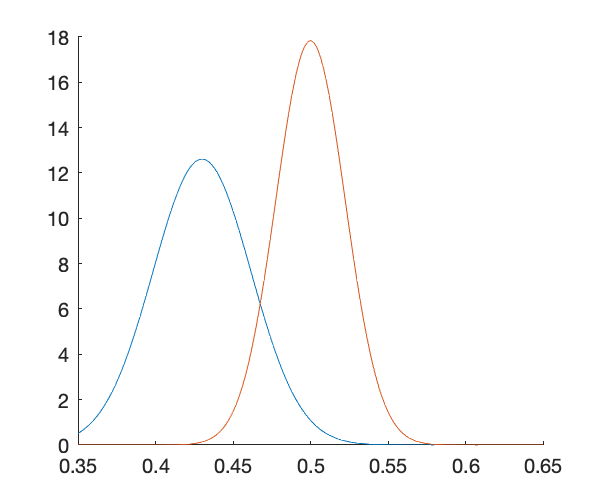

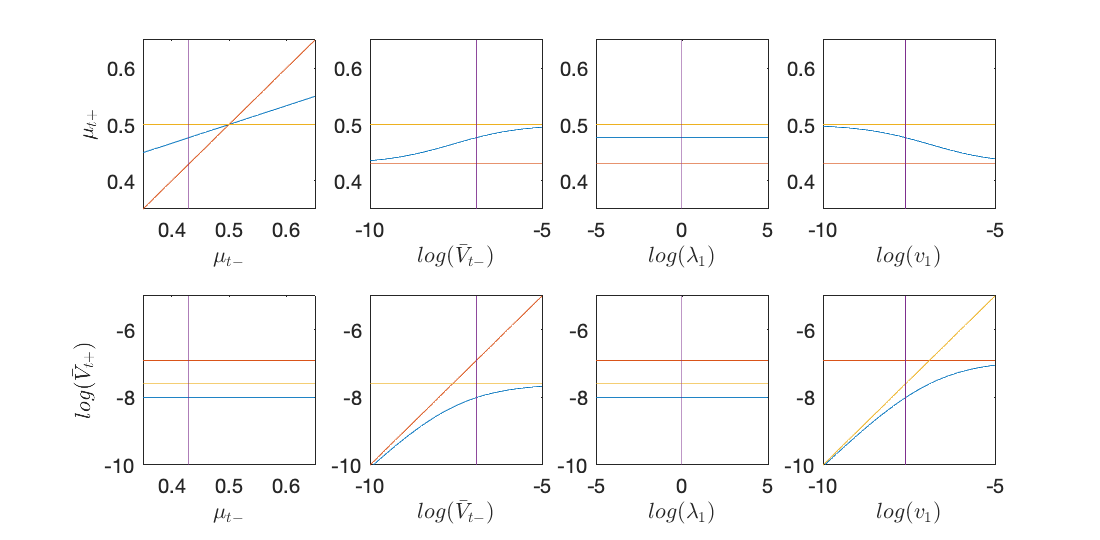

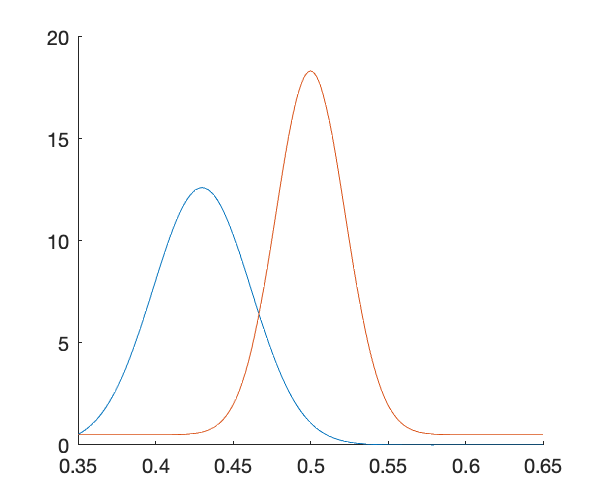

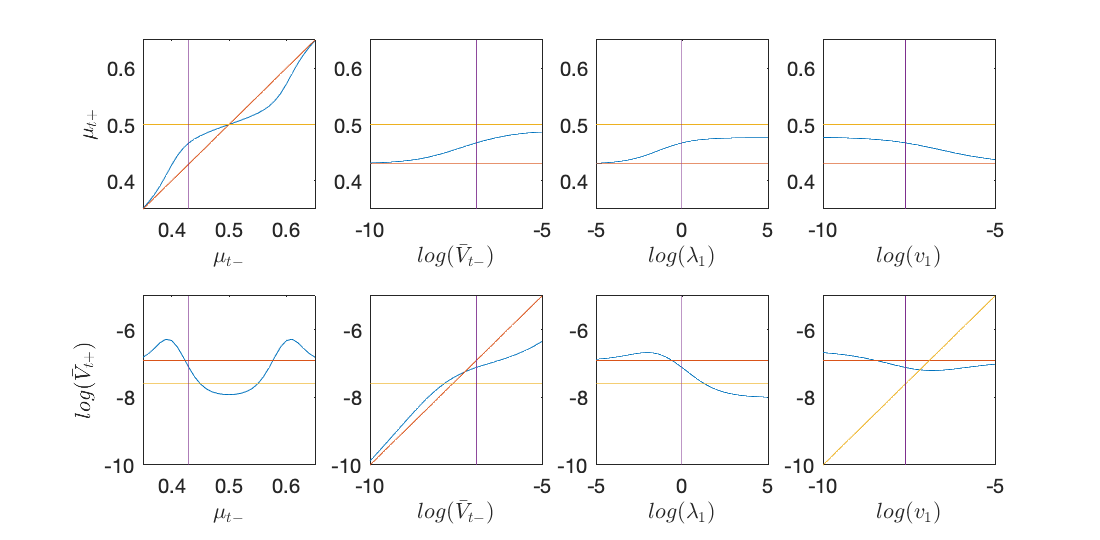


exp_var = 0.0005;
pre_var = 0.001;
pre_mean = 0.43;
lambda_1 = 1;


for c = 1:2
    if c == 1
        lambda_0 = 0;
    else
        lambda_0 = .5;
    end



params = PIPPET_params(...
    'means_unit', [.5],...
    'variance_unit', [exp_var],...
    'expected_period', .5,...
    'expected_cycles', 1,...
    'event_times', [], ...
    'lambda_unit', lambda_1,...
    'lambda_0', lambda_0);
s = params.streams{1};
gauss_distribution = @(x, mean, v) exp(-.5 * ((x - mean).^ 2) ./ v)./ (sqrt(2*pi*v));
phi_pre_list = .35:.002:.65;
figure()
set(gcf, 'Position',  [100, 100, 300,250])

hold on
xlim([.35, .65])
plot(phi_pre_list,gauss_distribution(phi_pre_list, pre_mean, pre_var));
plot(phi_pre_list,s.expect_func(phi_pre_list));

figure()
set(gcf, 'Position',  [100, 100, 550,270])

phi_pre_list = .35:.01:.65;

post_mean = zeros(size(phi_pre_list));
post_var = zeros(size(phi_pre_list));

    p = PIPPET_params(...
        'means_unit', [.5],...
        'variance_unit', [exp_var],...
        'expected_period', .5,...
        'expected_cycles', 1,...
        'event_times', [],...
        'lambda_unit', lambda_1,...
        'lambda_0', lambda_0);
    
for i = 1:length(phi_pre_list)

    post_mean(i) = p.streams{1}.phi_hat(phi_pre_list(i), pre_var);
    post_var(i) = p.streams{1}.V_hat(post_mean(i), phi_pre_list(i), pre_var);
end

subplot(2,4,1)
plot(phi_pre_list, post_mean);
hold on
plot(phi_pre_list, phi_pre_list)
plot(phi_pre_list, 0.5*ones(size(phi_pre_list)))
plot(0.43*[1,1], [0,1])
ylim([.35, .65])
xlabel('$\mu_{t-}$','Interpreter','Latex')
ylabel('$\mu_{t+}$','Interpreter','Latex')

subplot(2,4,5)
plot(phi_pre_list, log(post_var));
hold on
plot(phi_pre_list, log(pre_var)*ones(size(phi_pre_list)))
plot(phi_pre_list, log(exp_var)*ones(size(phi_pre_list)))
%plot(loglist, log(pre_var)*ones(size(loglist)))
plot(0.43*[1,1], [-10,-5])
%plot(loglist, v_1_list)
xlabel('$\mu_{t-}$','Interpreter','Latex')
ylabel('$log(\bar{V}_{t+})$','Interpreter','Latex')
ylim([-10,-5])

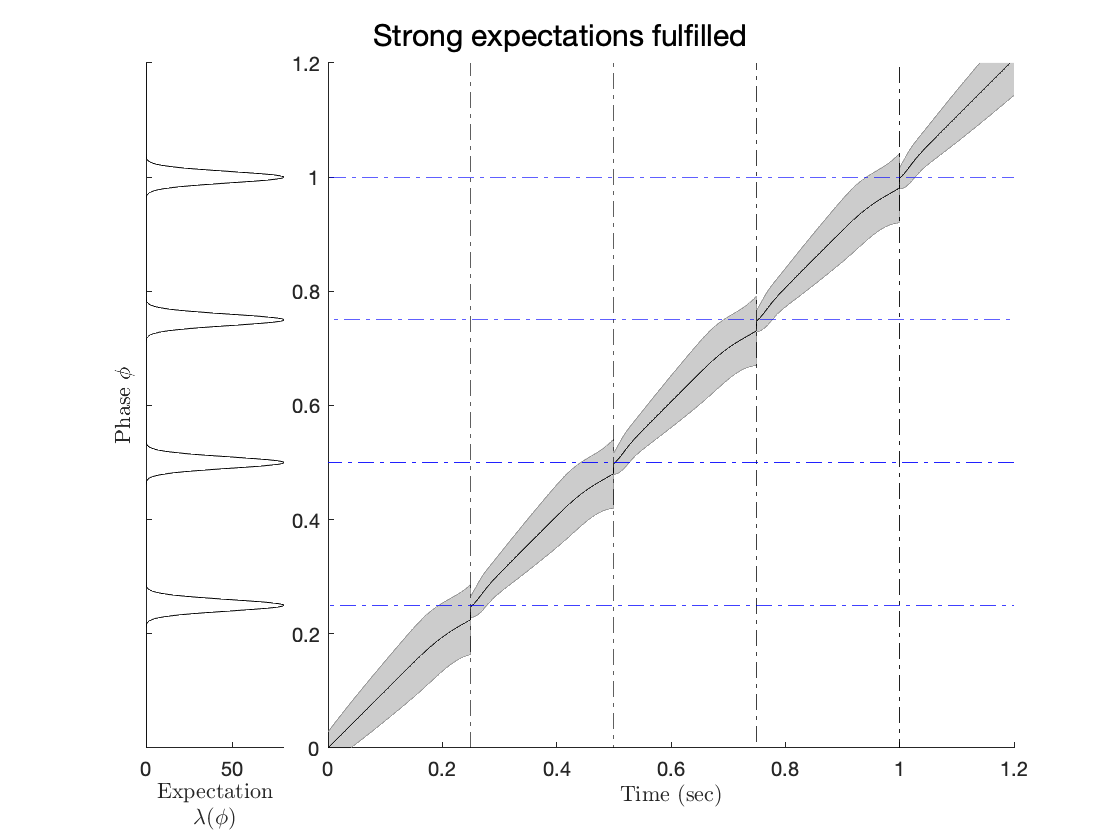


loglist = -10:.05:-5;
V_pre_list = exp(loglist);
post_mean = zeros(size(loglist));
post_var = zeros(size(loglist));

    p = PIPPET_params(...
        'means_unit', [.5],...
        'variance_unit', [exp_var],...

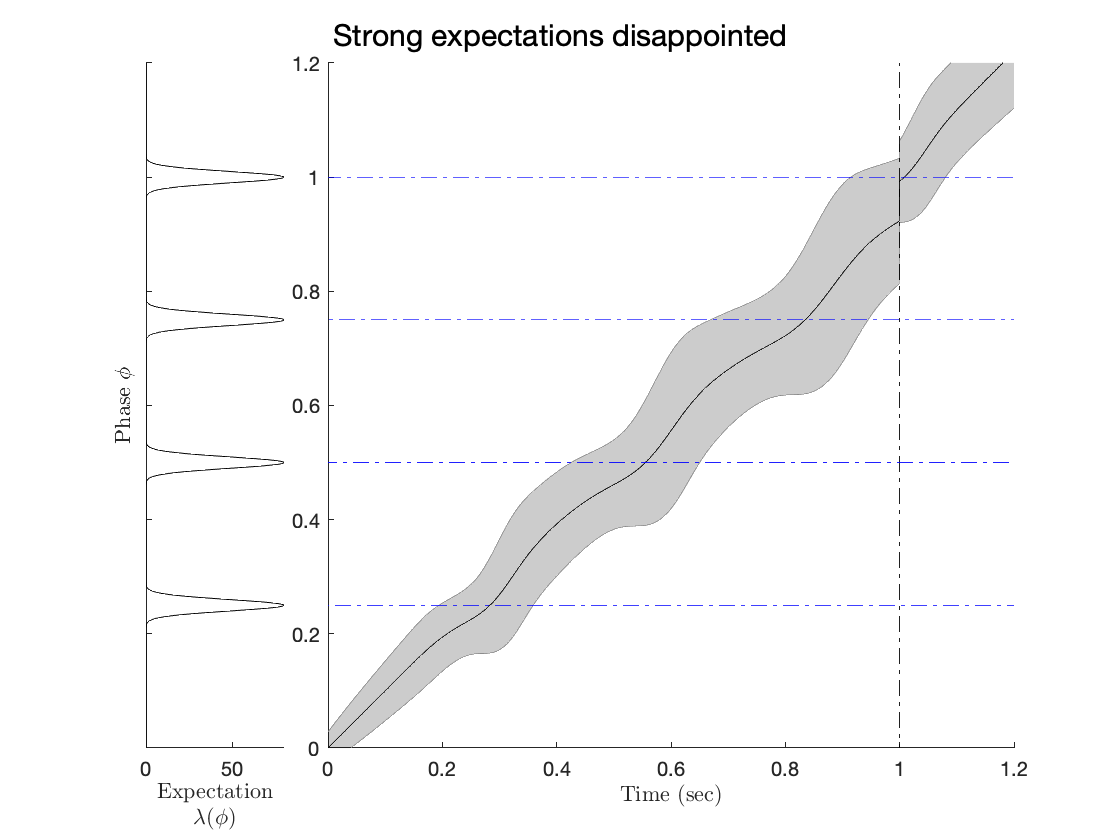

        'expected_period', .5,...
        'expected_cycles', 1,...
        'event_times', [],...
        'lambda_unit', lambda_1,...
        'lambda_0', lambda_0);
    
for i = 1:length(V_pre_list)

    post_mean(i) = p.streams{1}.phi_hat(pre_mean, V_pre_list(i));
    post_var(i) = p.streams{1}.V_hat(post_mean(i), pre_mean, V_pre_list(i));

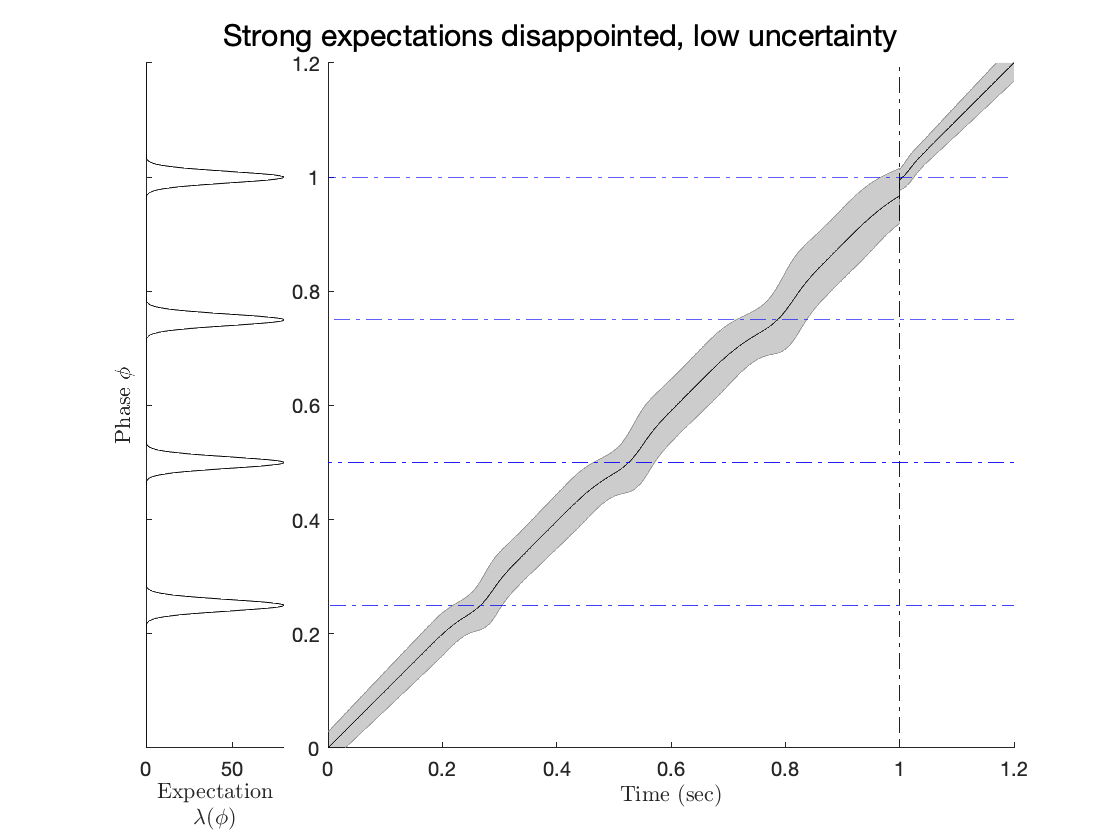

end

subplot(2,4,2)
plot(loglist, post_mean);
hold on
plot(loglist, pre_mean*ones(size(loglist)))
plot(loglist, 0.5*ones(size(loglist)))
plot(log(.001)*[1,1], [0,1])
ylim([.35, .65])
xlabel('$log(\bar{V}_{t-})$','Interpreter','Latex')

%ylabel('$\mu_{t+}$','Interpreter','Latex')

subplot(2,4,6)
plot(loglist, log(post_var));
hold on
plot(loglist, loglist)
plot(loglist, log(exp_var)*ones(size(loglist)))
%plot(loglist, log(pre_var)*ones(size(loglist)))
plot(log(.001)*[1,1], [-10,-5])
%plot(loglist, v_1_list)
xlabel('$log(\bar{V}_{t-})$','Interpreter','Latex')
%ylabel('$log(\bar{V}_{t+})$','Interpreter','Latex')
ylim([-10,-5])

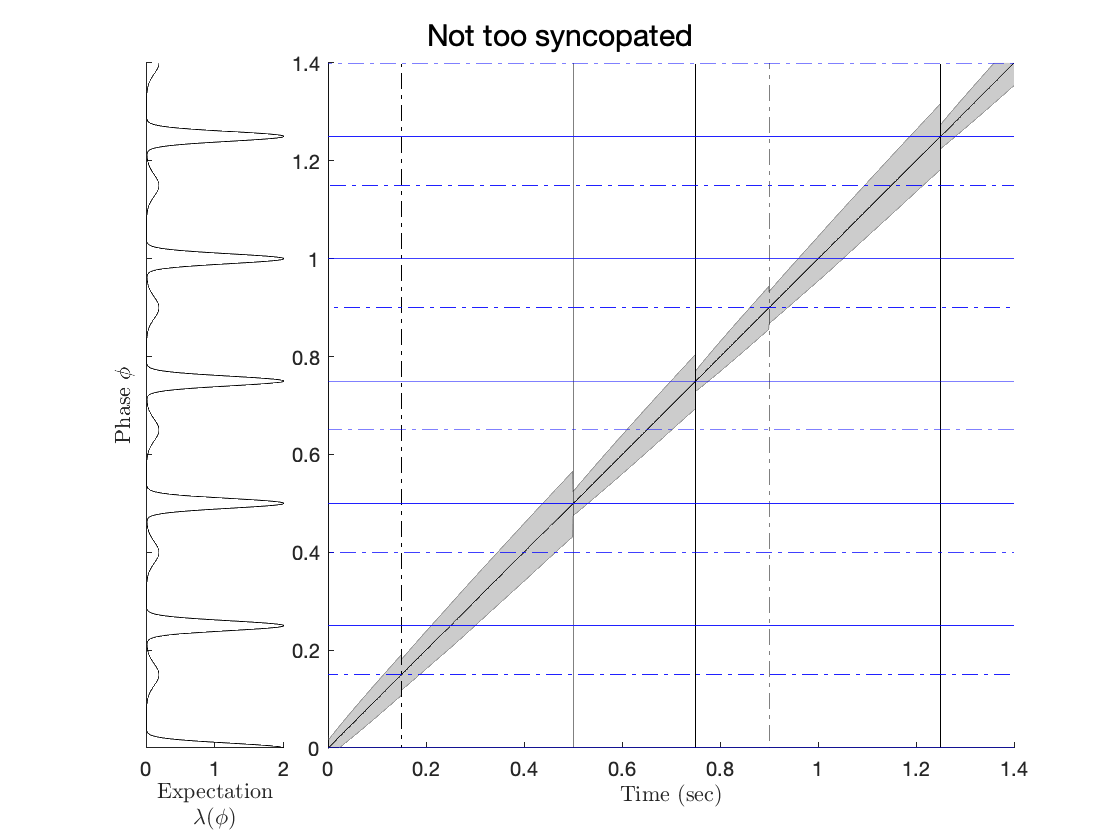



lambda_1_list = 1*exp(-5:.05:5);
loglist = log(lambda_1_list);
post_mean = zeros(size(loglist));
post_var = zeros(size(loglist));
pre_mean = 0.43;
pre_var = 0.001;

for i = 1:length(lambda_1_list)
    p = PIPPET_params(...
        'means_unit', [.5],...

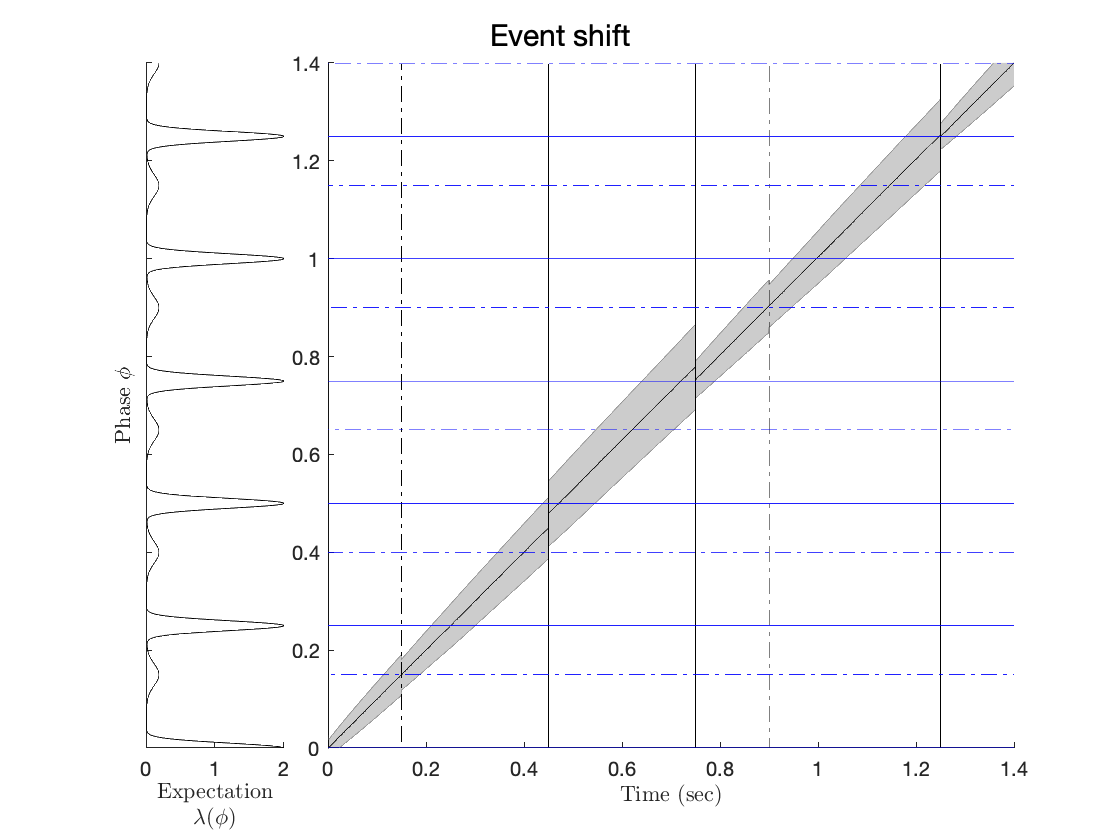

        'variance_unit', [exp_var],...
        'expected_period', .5,...
        'expected_cycles', 1,...
        'event_times', [],...
        'lambda_unit', [lambda_1_list(i)],...
        'lambda_0', lambda_0);

    post_mean(i) = p.streams{1}.phi_hat(pre_mean, pre_var);
    post_var(i) = p.streams{1}.V_hat(post_mean(i), pre_mean, pre_var);
end

subplot(2,4,3)
plot(loglist, post_mean);
hold on
plot(loglist, pre_mean*ones(size(loglist)))
plot(loglist, 0.5*ones(size(loglist)))
%plot(loglist, phihat_1*ones(size(loglist)))
plot(log(lambda_1)*[1,1], [0,1])
ylim([.35, .65])
xlabel('$log(\lambda_1)$','Interpreter','Latex')
%ylabel('$\mu_{t+}$','Interpreter','Latex')

subplot(2,4,7)
plot(loglist, log(post_var));

hold on
plot(loglist, log(pre_var)*ones(size(loglist)))
plot(loglist, log(exp_var)*ones(size(loglist)))
%plot(loglist, Vhat_1*ones(size(loglist)))
plot(log(lambda_1)*[1,1], [-10,-5])
xlabel('$log(\lambda_1)$','Interpreter','Latex')
%ylabel('$log(\bar{V}_{t+})$','Interpreter','Latex')
ylim([-10,-5])

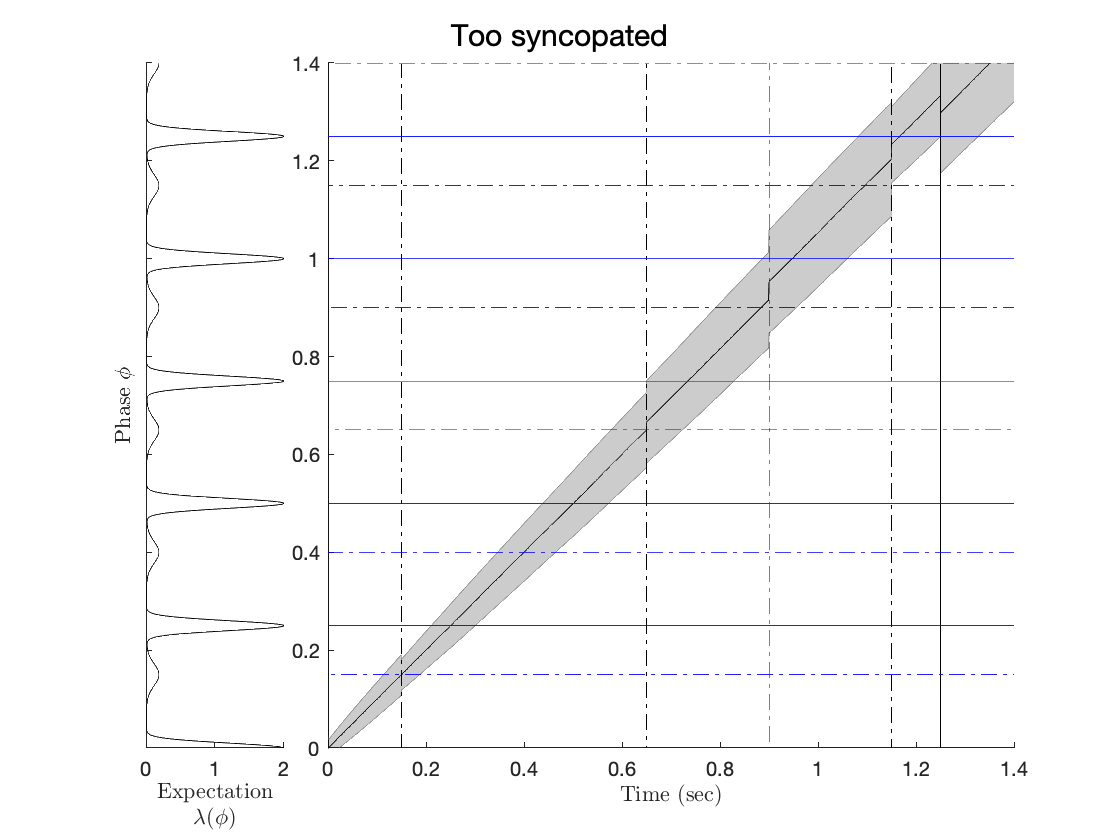

v_1_list = exp(-10:.05:-5);
loglist = log(v_1_list);
post_mean = zeros(size(loglist));
post_var = zeros(size(loglist));

for i = 1:length(v_1_list)
    p = PIPPET_params(...
        'means_unit', [.5],...
        'expected_period', .5,...
        'expected_cycles', 1,...
        'event_times', [],...
        'variance_unit', [v_1_list(i)],...
        'lambda_unit', lambda_1,...
        'lambda_0', lambda_0);

    post_mean(i) = p.streams{1}.phi_hat(pre_mean, pre_var);
    post_var(i) = p.streams{1}.V_hat(post_mean(i), pre_mean, pre_var);
end

subplot(2,4,4)
plot(loglist, post_mean);
hold on
plot(loglist, pre_mean*ones(size(loglist)))
plot(loglist, 0.5*ones(size(loglist)))
plot(log(exp_var)*[1,1], [0,1])

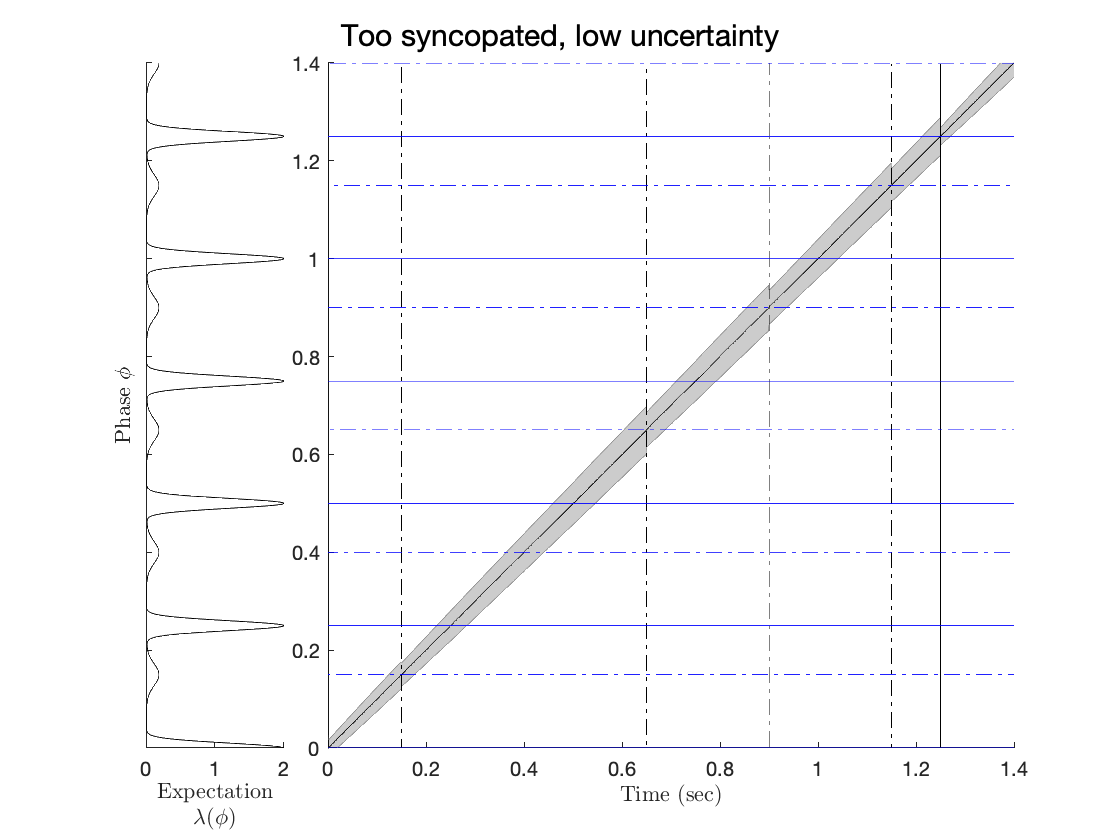

ylim([.35, .65])
xlabel('$log(v_1)$','Interpreter','Latex')
%ylabel('$\mu_{t+}$','Interpreter','Latex')
xlim([loglist(1),loglist(end)])

subplot(2,4,8)
plot(loglist, log(post_var));
hold on
plot(loglist, log(pre_var)*ones(size(loglist)))
plot(loglist, loglist)
plot(log(exp_var)*[1,1], [-10,-5])
%plot(loglist, v_1_list)
xlabel('$log(v_1)$','Interpreter','Latex')
%ylabel('$log(\bar{V}_{t+})$','Interpreter','Latex')

ylim([-10,-5])
xlim([loglist(1),loglist(end)])



end

## Time warping

What happens with strong expectations when nothing happens, as compared to when expectations are met? Time dilation!

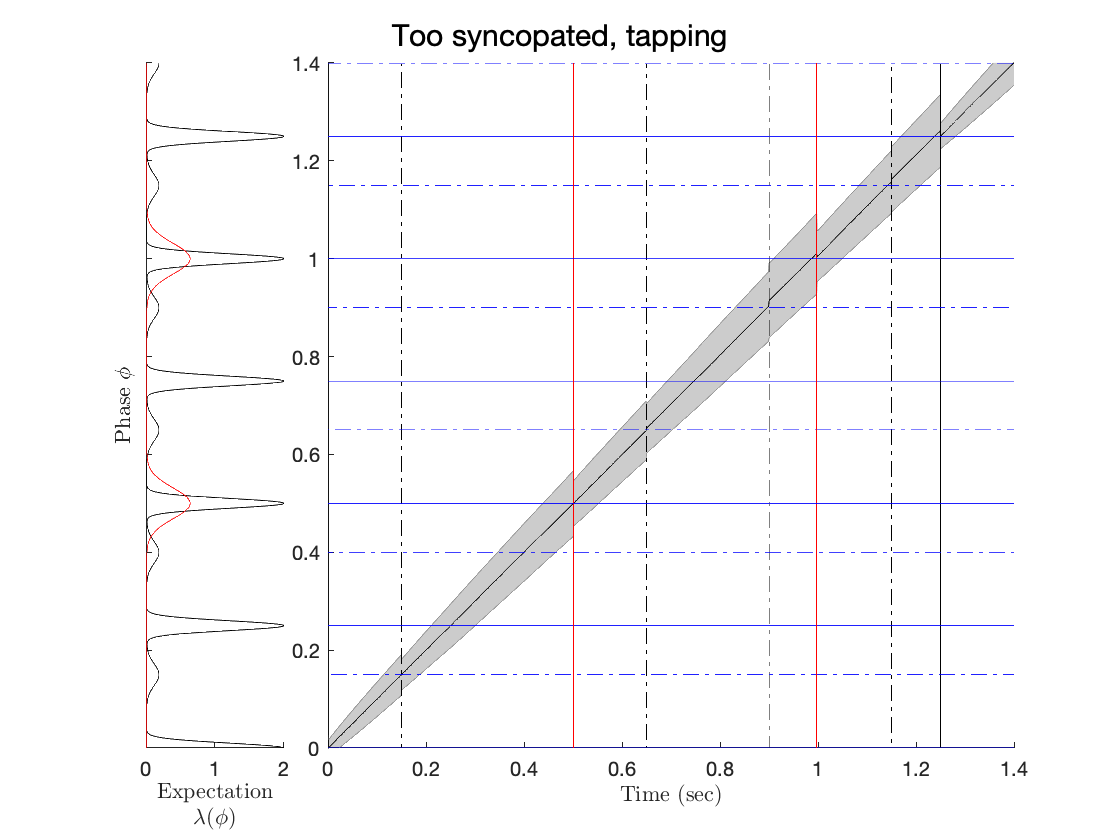



params = PIPPET_params(...

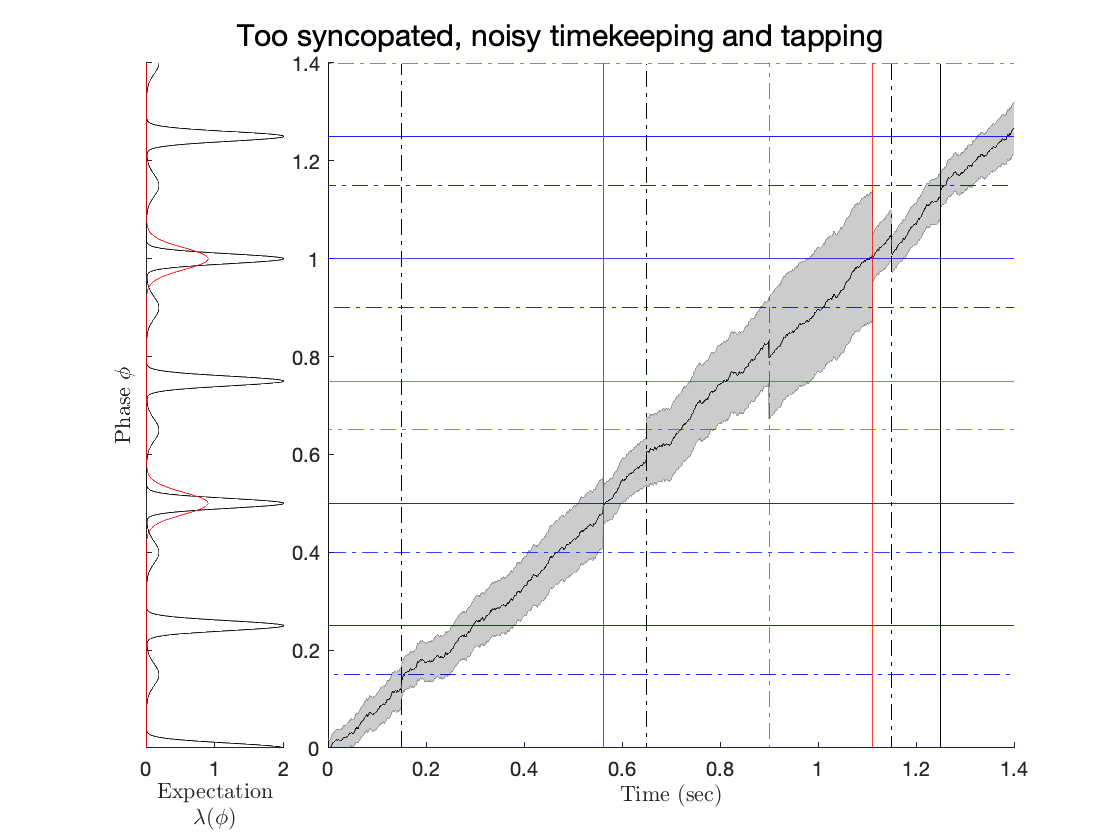

    'dt', .001,...
    'lambda_unit', 100*0.02,...
    'event_times',[.25, .5,.75, 1],...
    'sigma_phi',0.07,...
    'V_0', 0.0002,...
    'title', 'Strong expectations fulfilled');
[phibar_list, V_list] = run_PIPPET(params);

params2 = PIPPET_params(...
    'dt', .001,...
    'lambda_unit', 100*0.02,...
    'event_times',[1],...
    'sigma_phi',0.07,...
    'V_0', 0.0002,...
    'title', 'Strong expectations disappointed');

[phibar_list, V_list] = run_PIPPET(params2);


params3 = PIPPET_params(...
    'dt', .001,...
    'lambda_unit', 100*0.02,...
    'event_times',[1],...
    'sigma_phi',0.03,...
    'V_0', 0.0002,...
    'title', 'Strong expectations disappointed, low uncertainty');

[phibar_list, V_list] = run_PIPPET(params3);



## Swingin'

The filter detects and adjusts to a phase shift in a swung rhythm.

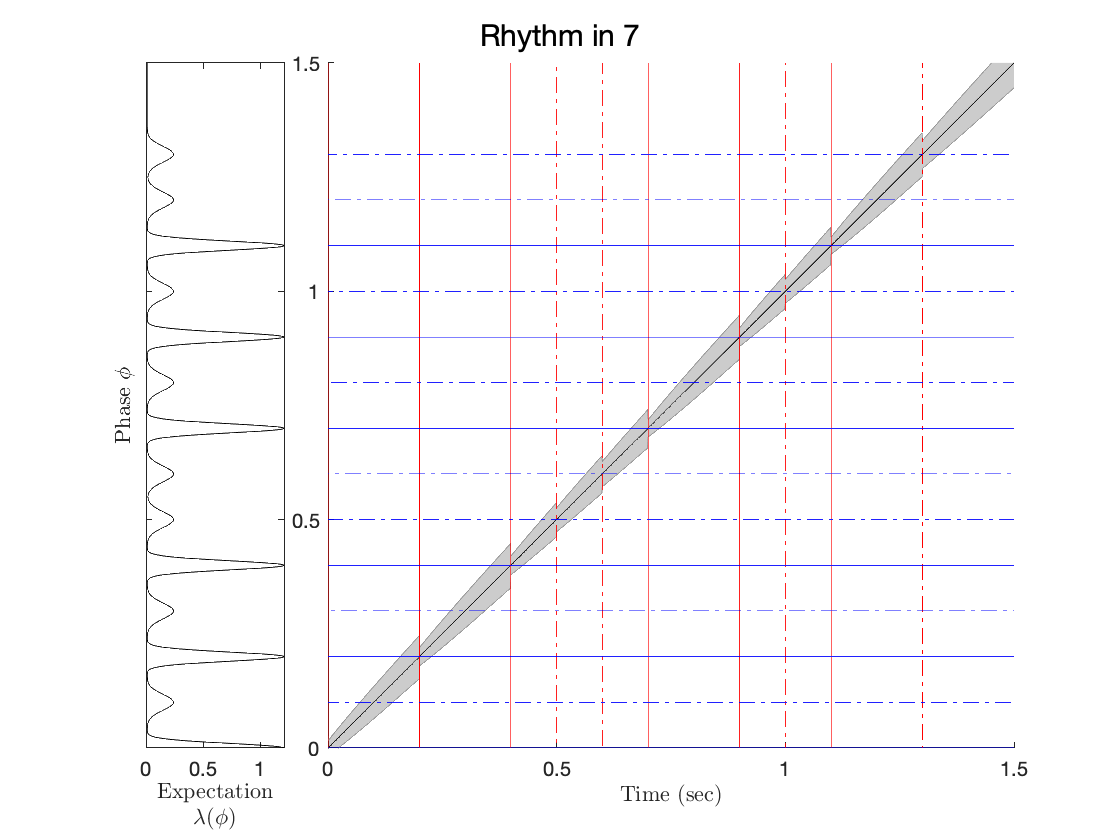

event_times = [0, 0.150, .5, .75, .9, 1.25];

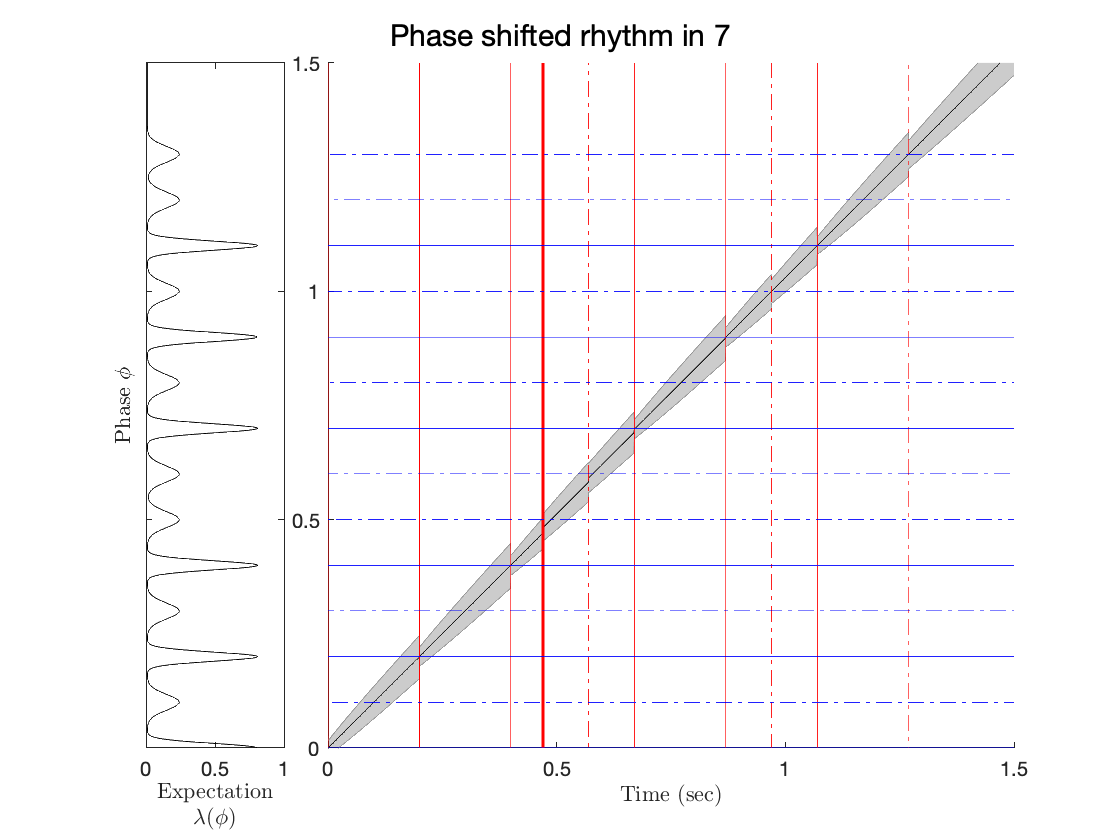

highlight_event_indices = [1,0,1,1,0,1];
highlight_expectations = [1,0];

if make_sounds
    times_w_lead = [0, .5, event_times+1];
    identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/low_sync.wav', snd, 44100);
end

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...

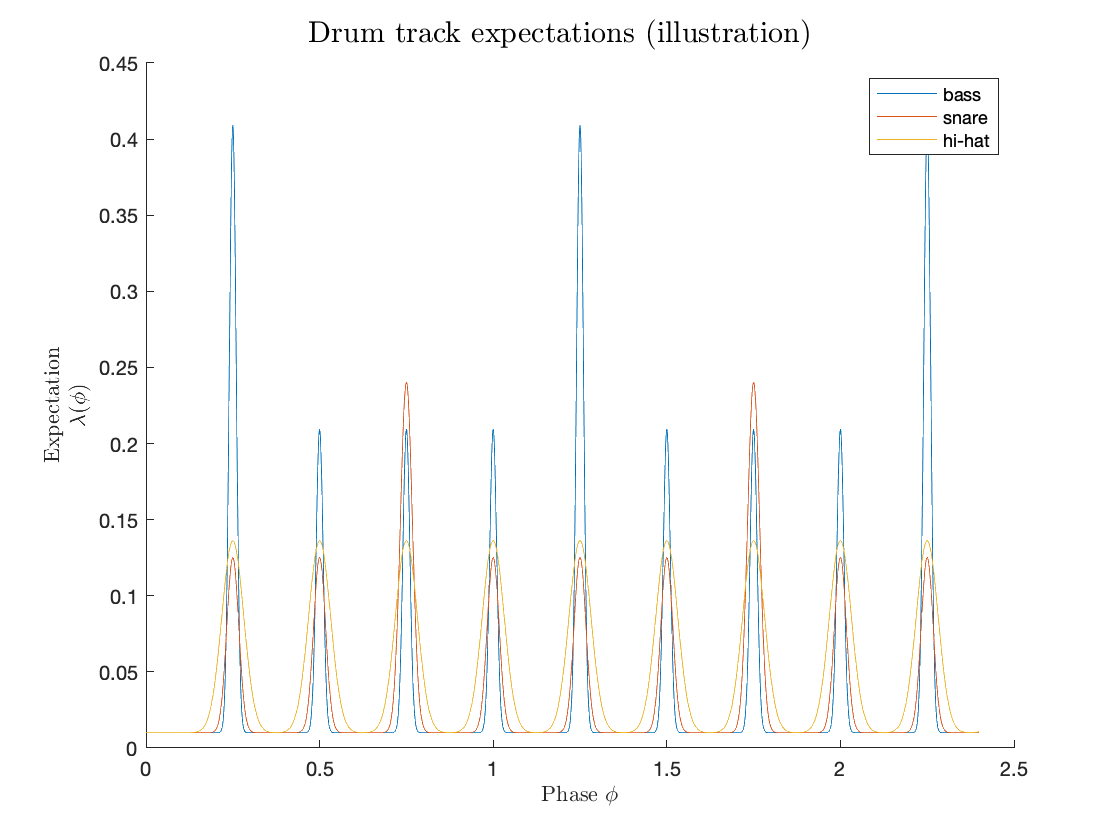

    'highlight_expectations', highlight_expectations, ...
    'title', 'Not too syncopated','tmax', 1.4);
[phibar_list, V_list] = run_PIPPET(params);

event_times = [0, 0.150, .5, .75, .9, 1.25];
event_times(3) = event_times(3)-.05;
highlight_event_indices = [1,0,1,1,0,1];
highlight_expectations = [1,0];

if make_sounds
    times_w_lead = [0, .5, event_times+1];
    identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/low_sync_ES.wav', snd, 44100);
end

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Event shift','tmax', 1.4);

[phibar_list, V_list] = run_PIPPET(params);
event_times = [0, 0.150, .5, .75, .9, 1.25];
event_times(4:end) = event_times(4:end)-.05;
highlight_event_indices = [1,0,1,1,0,1];
highlight_expectations = [1,0];

if make_sounds
    times_w_lead = [0, .5, event_times+1];
    identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];

    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/low_sync_PS.wav', snd, 44100);
end

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Phase shift','tmax', 1.4);
[phibar_list, V_list] = run_PIPPET(params);

## Confused

If expected timing of subdivisions is not sufficiently precise, swung and syncopated rhythms can be confusing!

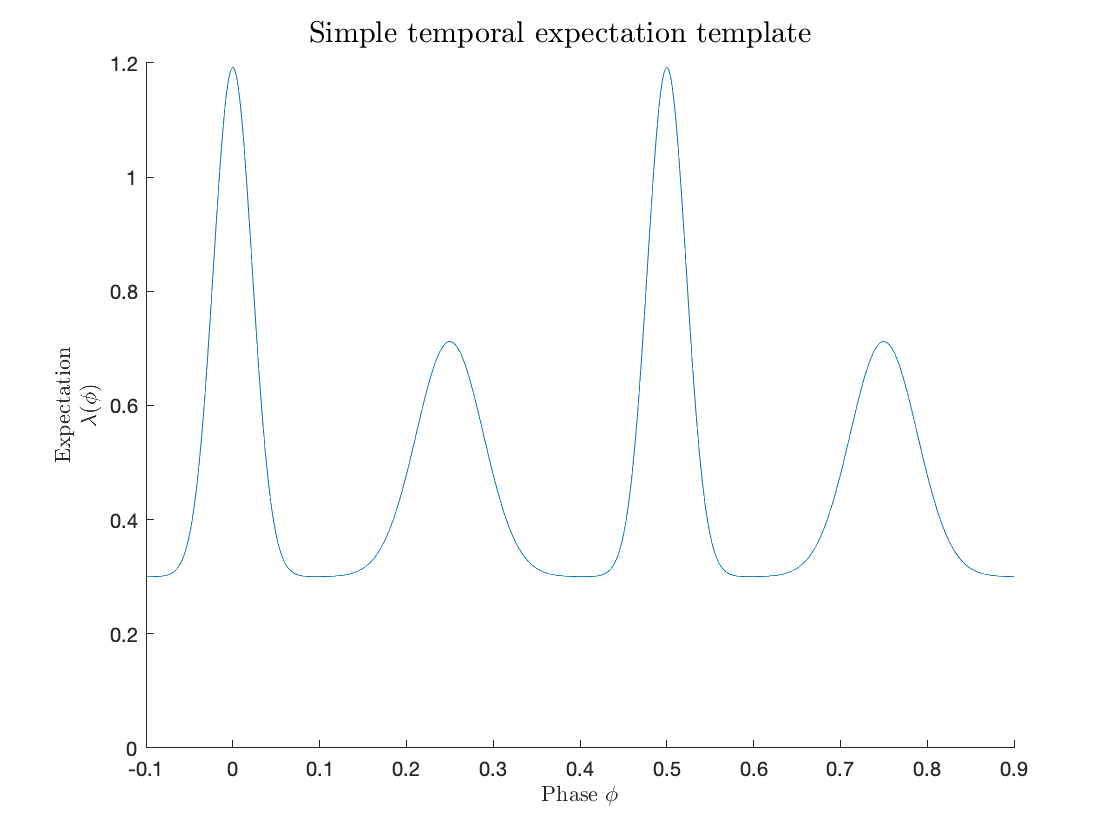


event_times = [0, 0.150, .65, .9, 1.15, 1.25];
highlight_event_indices = [1,0,0,0,0,1];


if make_sounds
    times_w_lead = [0, .5, event_times+1];
    identities = [sp.beep_index, sp.beep_index, sp.standard_index*ones(size(event_times))];
    snd = stim_maker_etime(stretch*times_w_lead, identities, sp);
    audiowrite('sounds/hi_sync.wav', snd, 44100);
end

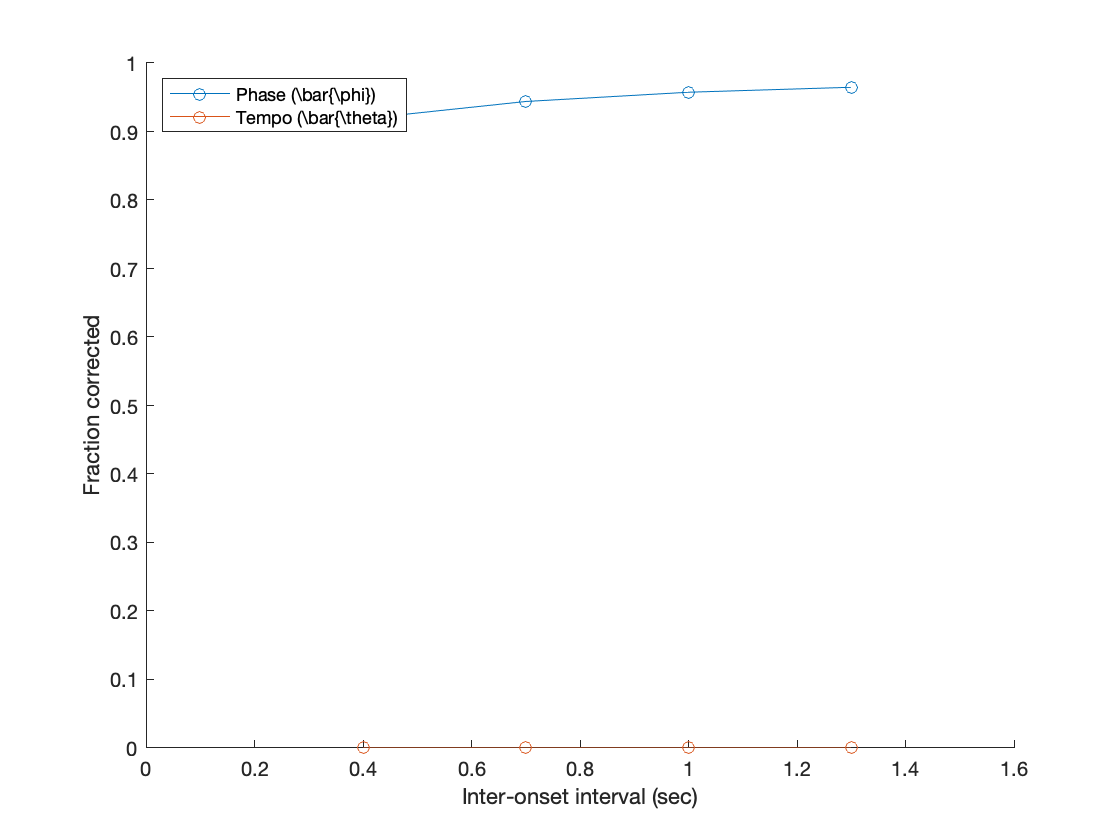

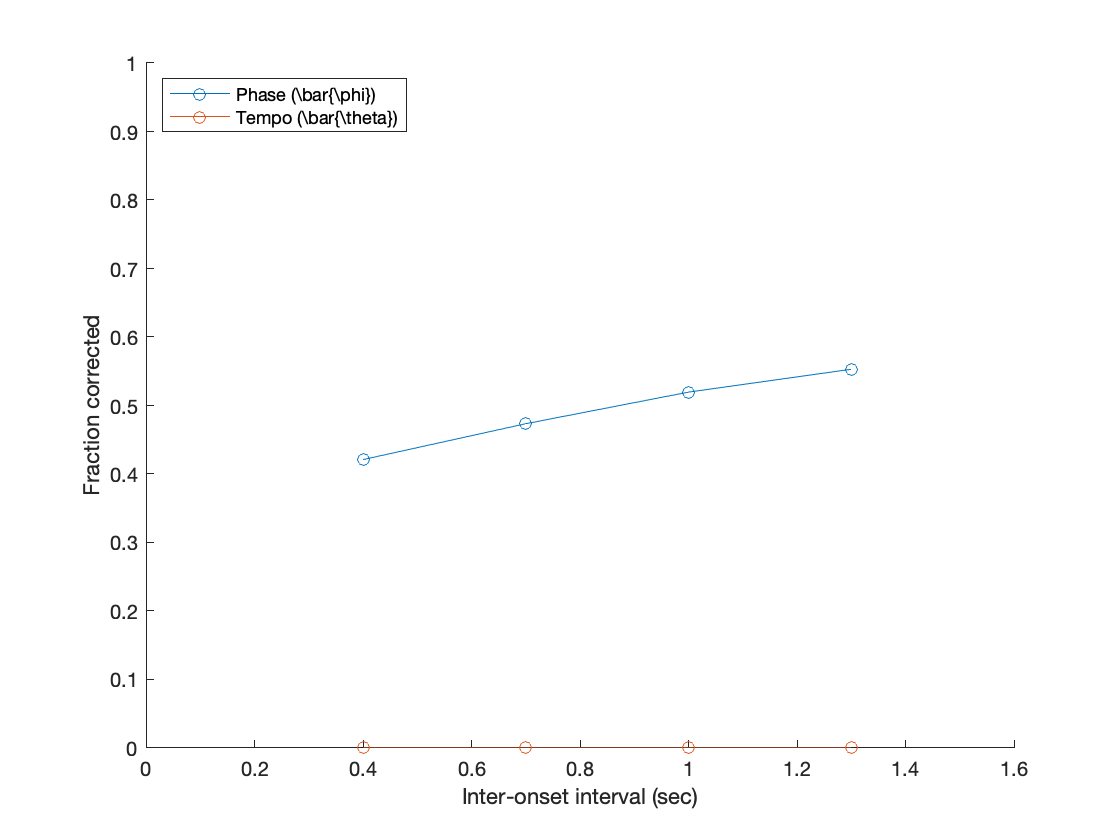


params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Too syncopated','tmax', 1.4);

[phibar_list, V_list] = run_PIPPET(params);


params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'sigma_phi', 0.03,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Too syncopated, low uncertainty','tmax', 1.4);

[phibar_list, V_list] = run_PIPPET(params);

params = PIPPET_params(...
    'n_streams', 2,...
    'means_unit', {[0, .15], .5},...
    'variance_unit', {[.0001, .0005], .001},...
    'lambda_unit', {[.05, .01], .05},...
    'expected_period', {.25, .5},...
    'expected_cycles', {6, 3},...
    'event_times', {event_times, []}, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'tapping', true,...
    'title', 'Too syncopated, tapping','tmax', 1.4);

[phibar_list, V_list, params] = run_PIPPET(params);

subplot(1,5, 2:5)
xlim([0, 1.4])

params = PIPPET_params(...
    'n_streams', 2,...
    'means_unit', {[0, .15], .5},...
    'variance_unit', {[.0001, .0005], .0005},...
    'lambda_unit', {[.05, .01], .05},...
    'expected_period', {.25, .5},...
    'expected_cycles', {6, 3},...
    'event_times', {event_times, []}, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'tapping', true,...
    'sigma_phi', .05,...
    'eta_phi', 0.05,...
    'motor_eta', 0.01,...
    'title', 'Too syncopated, noisy timekeeping and tapping','tmax', 1.4);

[phibar_list, V_list, params] = run_PIPPET(params);

## In seven

The filter detects and adjusts to a phase shift in a 7/8 groove.

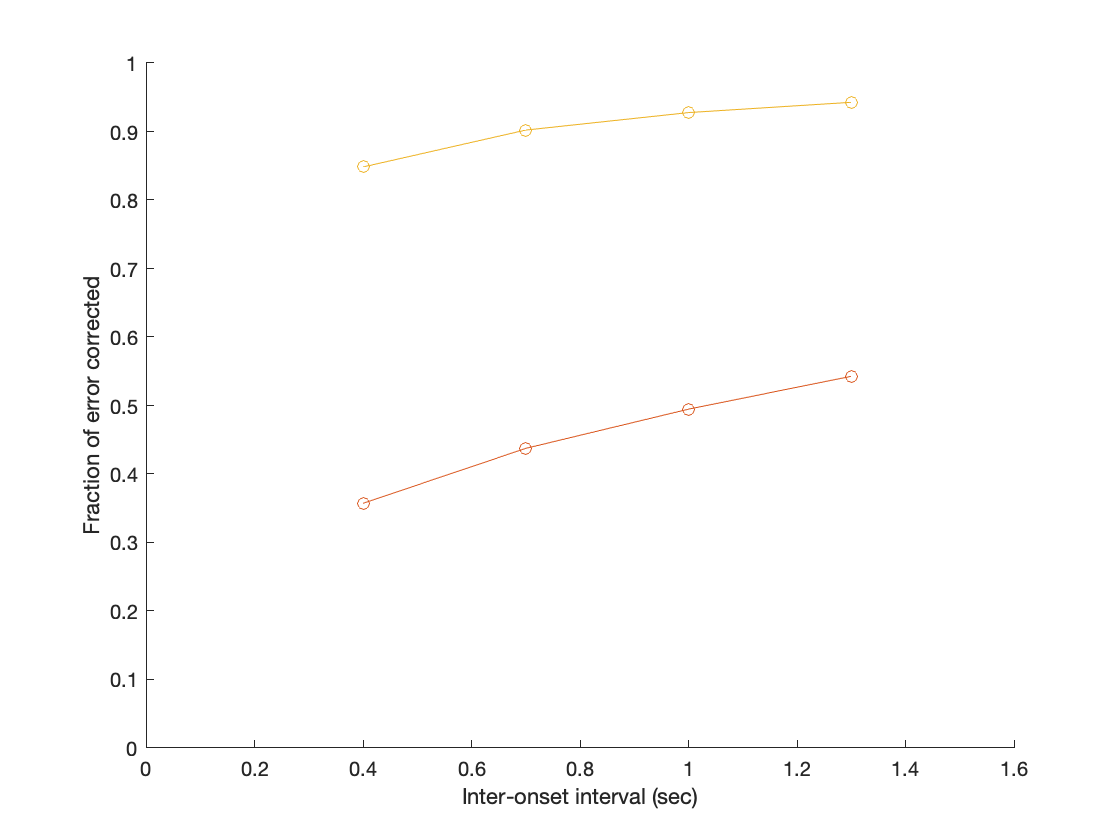


event_times = [0, .2, .4, .5, .6, .7, .9, 1, 1.1, 1.3];
highlight_event_indices = [1, 1, 1, 0, 0, 1, 1, 0, 1, 0];
highlight_expectations = [1,0,1,0,1,0,0];
params = PIPPET_params(...
    'means_unit', 0:.1:.6,...
    'variance_unit', [.0001, .0003, .0001, .0003, .0001, .0003, .0003],...
    'lambda_unit', [.03, .01,.03, .01,.03, .01,.01],...
    'expected_cycles', 2,...
    'expected_period', .7,...
    'event_times', event_times, ...

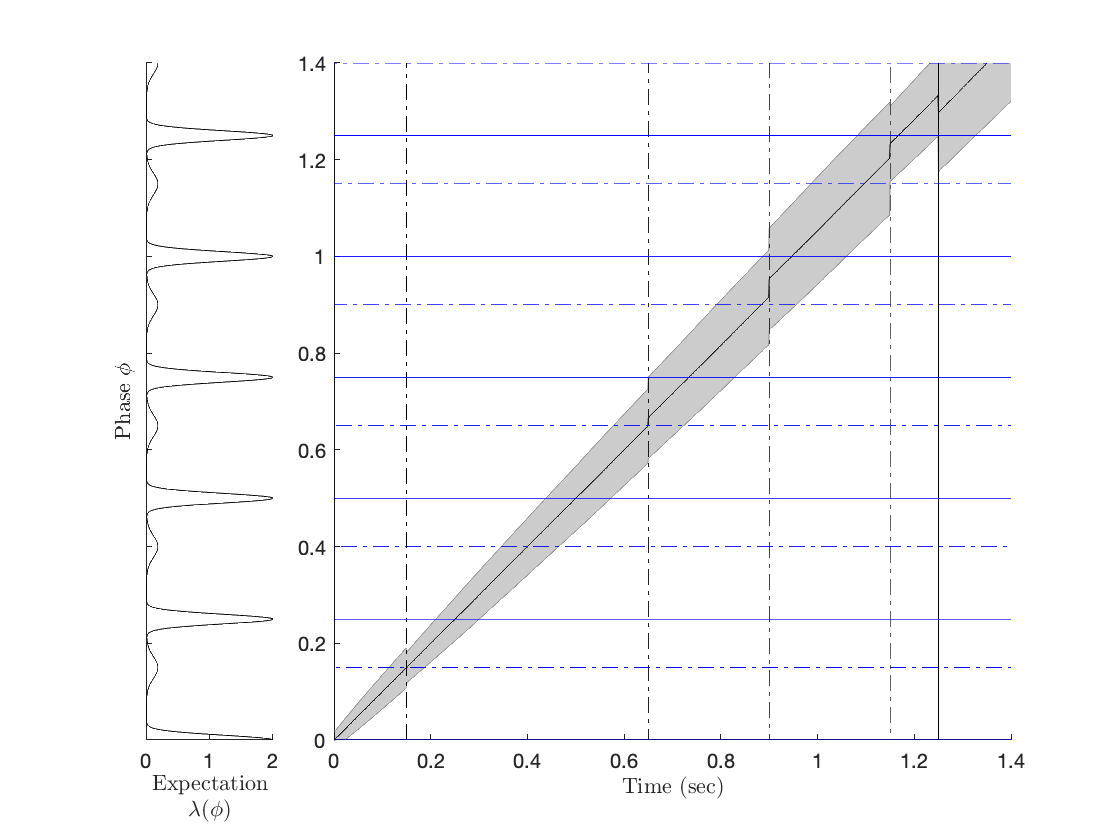

    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Rhythm in 7', ...
    'tmax', 1.5);
[phibar_list, V_list] = run_PIPPET(params);


event_times(4:end)=event_times(4:end)-.03;
highlight_event_indices(4) = 2;

params = PIPPET_params(...
    'means_unit', 0:.1:.6,...
    'variance_unit', [.0001, .0003, .0001, .0003, .0001, .0003, .0003],...
    'lambda_unit', [.02, .01,.02, .01,.02, .01,.01],...
    'expected_cycles', 2,...
    'expected_period', .7,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...

    'title', 'Phase shifted rhythm in 7', ...
    'tmax', 1.5);
[phibar_list, V_list] = run_PIPPET(params);


## Drum track expectations

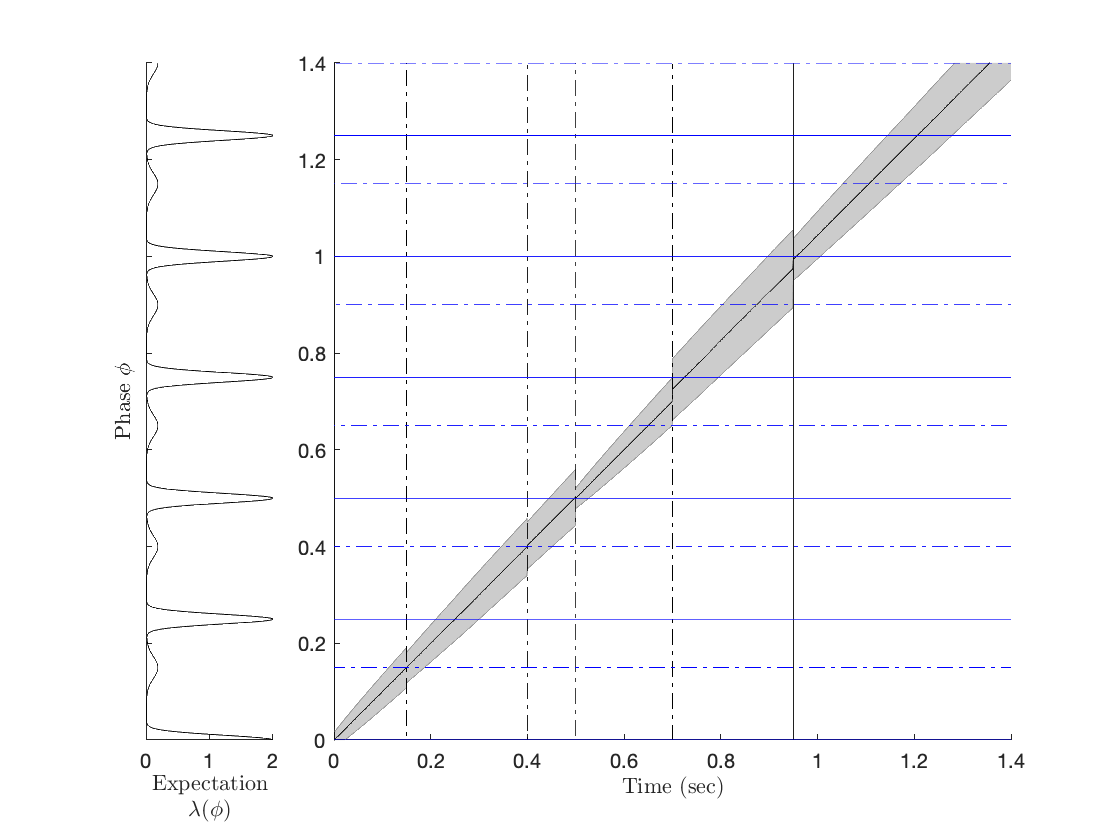

bass_variance = 0.0001*[1,1,1,1];

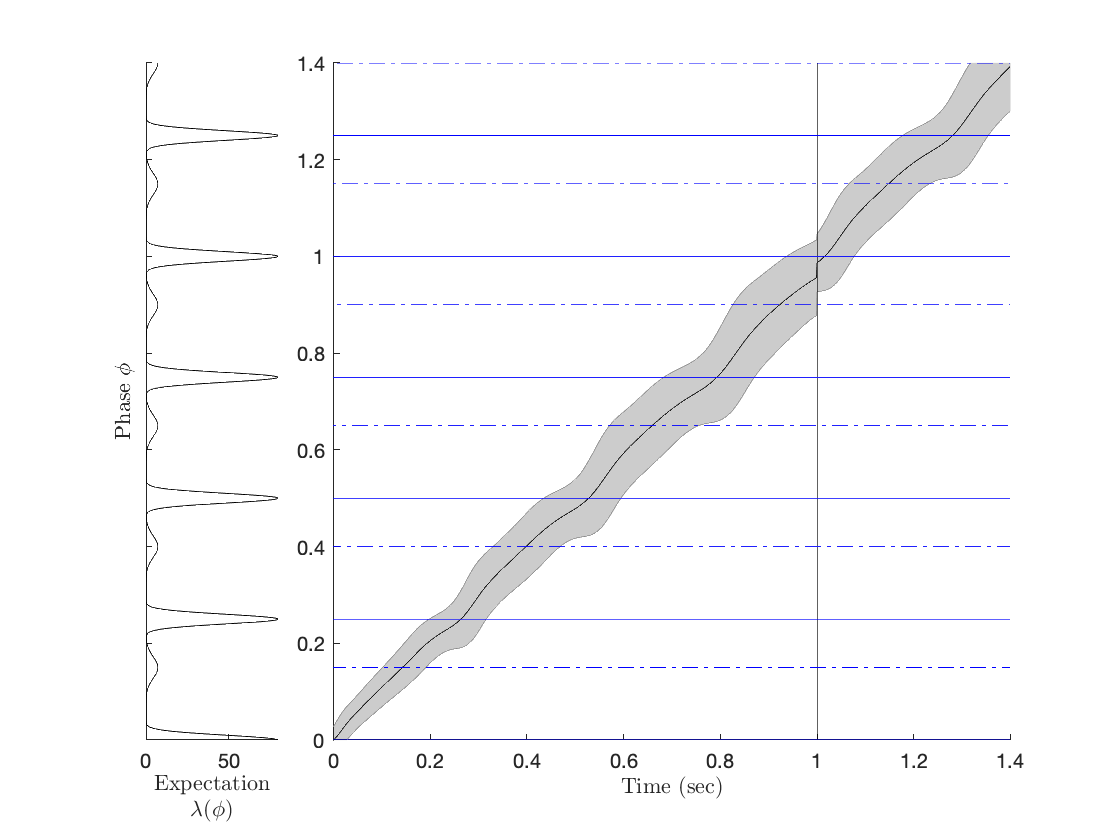

snare_variance = 0.0003*[1,1,1,1];
hihat_variance = 0.001*[1,1,1,1];

bass_lambda = [.01, .005, .005, .005];
snare_lambda = [.005, .005, .01, .005];
hihat_lambda = [.01, .01, .01, .01];

means = [.25, .5, .75, 1];

params = PIPPET_params(...
    'n_streams', 3,...
    'means_unit', {means, means, means},...

    'variance_unit', {bass_variance, snare_variance, hihat_variance},...
    'lambda_unit', {bass_lambda, snare_lambda, hihat_lambda},...
    'lambda_0', {.01, .01, .01},...
    'expected_cycles', 3,...
    'expected_period', 1,...
    'event_times', {[],[],[]},...
    'title', 'Drum track');

xlist = 0:.001:2.4;
figure()
hold on;
plot(xlist, params.streams{1}.expect_func(xlist))
plot(xlist, params.streams{2}.expect_func(xlist))
plot(xlist, params.streams{3}.expect_func(xlist))
legend('bass', 'snare', 'hi-hat')
xlabel('Phase $\phi$','Interpreter','Latex')
ylabel({'Expectation';'$\lambda(\phi)$'},'Interpreter','Latex');
sgtitle('Drum track expectations (illustration)','Interpreter','Latex')


## Basic expectations

bass_variance = 0.0005*[1,3,1,3];

bass_lambda = [.05, .04, .05, .04];

means = [0, .25, .5, .75];

params = PIPPET_params(...
    'n_streams', 1,...
    'means_unit', {means},...
    'variance_unit', {bass_variance},...
    'lambda_unit', {bass_lambda},...
    'lambda_0', {.3},...
    'expected_cycles', 3,...
    'expected_period', 1,...
    'event_times', {[],[],[]},...
    'title', 'Drum track');

xlist = -.1:.001:.9;
figure()
hold on;
plot(xlist, params.streams{1}.expect_func(xlist))
ylim([0, 1.2])
xlim([-.1, .9])
%legend('bass')
xlabel('Phase $\phi$','Interpreter','Latex')
ylabel({'Expectation';'$\lambda(\phi)$'},'Interpreter','Latex');
sgtitle('Simple temporal expectation template','Interpreter','Latex')

## Phase shift (no period adjustment)


sigma_list = [0.05, 0.01, 0.05];
period_list = [.4, .7, 1, 1.3];
alpha_list = zeros(length(sigma_list), length(period_list));
for c=1:length(sigma_list)



%%% Any of the following phase shift schemes give similar results.

%delta_list = -period_list.^2 / 20; % phase shifts corresponding to equal tempo changes
%delta_string = "\Delta = IOI^2 / 20";
delta_list = -period_list / 25; % phase shifts proportional to period
delta_string = "\Delta = IOI/25";
%delta_list = -.01*ones(size(period_list)); % identical phase shifts
%delta_string = "\Delta = 0.01 sec";


xbar_final_list = zeros(1, length(period_list));
xbar_initial_list = zeros(1, length(period_list));
Sigma_final_list = zeros(1,1, length(period_list));
Sigma_initial_list = zeros(1,1, length(period_list));

for i = 1:length(period_list)
    event_times=[period_list(i), 2*period_list(i), 3*period_list(i), 4*period_list(i)+delta_list(i)];
    params = PIPPET_params(...
        'event_times', event_times,...
    'means_unit', [period_list(i)],...
    'variance_unit', [.0002],...
    'expected_cycles', 4,...
    'expected_period', period_list(i),...
    'sigma_phi', sigma_list(c),...
    'lambda_0', .0000001,...
    'V_0', .0001,...
    'tmax', 4*period_list(i)+delta_list(i),...
    'title', "IOI = " + num2str(period_list(i))+ " sec, "+delta_string,...
    'display', false);

    
    [xbar_list, Sigma_list] = run_PIPPET(params);
    %ylim([1/period_list(i) - .15, 1/period_list(i)+.15])
    %xlim([3.6, 4.2])
    %plot([3.6, 4.2], [1,1]*(1./(period_list(i)+delta_list(i))));
    %subplot(5,1,5)
    %xlim([3.6, 4.2])
    xbar_final_list(:, i) = xbar_list(end);
    xbar_initial_list(:, i) = xbar_list(end-1);
    Sigma_final_list(:,:, i) = Sigma_list(end);
    Sigma_initial_list(:,:, i) = Sigma_list(end-1);
    
    
end

fourth_tap_times = 4*period_list;

phase_until_next_tap = 5*period_list - xbar_final_list(1,:);

time_until_next_tap = phase_until_next_tap./1;

fifth_tap_times = fourth_tap_times + delta_list + time_until_next_tap;

next_asynchrony = (5*period_list + delta_list) - fifth_tap_times;

alpha_list(c,:) = (delta_list-next_asynchrony)./delta_list;

figure()
hold on
plot(period_list, -(xbar_final_list(1,:)-xbar_initial_list(1,:))./(delta_list), 'o-')
plot(period_list, 0./(1./(period_list + delta_list) - 1./period_list), 'o-')
%plot(period_list, xbar_initial_list(1,:), 'o-')
ylabel('Fraction corrected')
xlabel('Inter-onset interval (sec)')
lgd = legend('Phase (\mu)', 'Tempo (\bar{\theta})');
lgd.Location = 'northwest';
xlim([0, 1.6])
ylim([0, 1])
%ylim([3.9, 4])

end

figure()
hold on
for c = 1:3
plot(period_list, alpha_list(c,:), 'o-')
end
%plot([0,1.6], [1,1], '-')
ylabel('Fraction of error corrected')
xlabel('Inter-onset interval (sec)')
xlim([0, 1.6])
ylim([0, 1])


All results with the same template

event_times = [0, 0.150, .65, .9, 1.15, 1.25];
highlight_event_indices = [1,0,0,0,0,1];
highlight_expectations = [1,0];

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'tmax', 1.4);

[phibar_list, V_list] = run_PIPPET(params);

event_times = [0, 0.150, .4, .5, .7, .95];

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'tmax', 1.4);

[phibar_list, V_list] = run_PIPPET(params);

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [2, .4],...
    'expected_cycles', 6,...
    'event_times', [1], ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'tmax', 1.4);

[phibar_list, V_list] = run_PIPPET(params);
